This notebook is created by 

*Asif Newaz*

*Lecturer, EEE, IUT*

*MATLAB version: 2022a*

## Import data

data = readtable('StormEvents_2018.csv')

data = 61742×23 table
    EpisodeID      Event_ID        State        Year        Month             Event_Type            Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                       

## Summary of the data

summary(data)

Variables:

    EpisodeID: 61742×1 double

        Values:

            Min       1.2126e+05
            Median    1.2693e+05
            Max        1.338e+05

    Event_ID: 61742×1 double

        Values:

            Min       7.2588e+05
            Median    7.6236e+05
            Max       8.0115e+05

    State: 61742×1 categorical

        Values:

            ALABAMA                   1005  
            ALASKA                     116  
            AMERICAN SAMOA               3  
            ARIZONA                    849  
            ARKANSAS                  1331  
            ATLANTIC NORTH             613  
            ATLANTIC SOUTH             697  
            CALIFORNIA                1599  
            COLORADO                  1761  
            CONNECTICUT                335  
            DELAWARE                    62  
            DISTRICT OF COLUMBIA        79  
            E PACIFIC                    4  
        

### Removing unnecessary variables

data(:,{'EpisodeID','Event_ID','Year','Event_Narrative','Episode_Narrative'})=[]

data = 61742×18 table
       State            Month             Event_Type            Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ____________    _____________    _____________________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________  

## Data Analysis

### Q1. Which states had the highest occurrence of events?

% similar to Pandas value_counts()
stg= groupcounts(data, 'State')

stg = 67×3 table
             State              GroupCount     Percent 
    ________________________    __________    _________

    {'ALABAMA'             }       1005          1.6277
    {'ALASKA'              }        116         0.18788
    {'AMERICAN SAMOA'      }          3       0.0048589
    {'ARIZONA'             }        849          1.3751
    {'ARKANSAS'            }       1331          2.1557
    {'ATLANTIC NORTH'      }        613         0.99284
    {'ATLANTIC SOUTH'      }        697          1.1289
    {'CALIFORNIA'          }       1599          2.5898
    {'COLORADO'            }       1761          2.8522
    {'CONNECTICUT'         }        335         0.54258
    {'DELAWARE'            }         62         0.10042
    {'DISTRICT OF COLUMBIA'}         79         0.12795
    {'E PACIFIC'           }          4       0.0064786
    {'FLORIDA'             }        985 

% sort the values in descending order
sortrows(stg, "GroupCount","descend")

ans = 67×3 table
          State           GroupCount    Percent
    __________________    __________    _______

    {'TEXAS'         }       3370       5.4582 
    {'VIRGINIA'      }       2999       4.8573 
    {'IOWA'          }       2715       4.3973 
    {'KANSAS'        }       2458       3.9811 
    {'SOUTH DAKOTA'  }       2089       3.3834 
    {'KENTUCKY'      }       2050       3.3203 
    {'NEW YORK'      }       1985        3.215 
    {'MISSOURI'      }       1944       3.1486 
    {'NORTH CAROLINA'}       1830       2.9639 
    {'COLORADO'      }       1761       2.8522 
    {'MINNESOTA'     }       1731       2.8036 
    {'NEBRASKA'      }       1708       2.7664 
    {'ILLINOIS'      }       1700       2.7534 
    {'CALIFORNIA'    }       1599       2.5898 
    {'PENNSYLVANIA'  }       1556       2.5202 
    {'OKLAHOMA'      }       1532       2.4813 


As we can see, Texas, Virginia, and Iowa had the most events. 

Some other states such as Delaware, Alaska had very small number of events.  

### Q2. Monthly occurrence of events

mg= groupcounts(data, 'Month')

mg = 12×3 table
        Month        GroupCount    Percent
    _____________    __________    _______

    {'April'    }       5504       8.9145 
    {'August'   }       5781       9.3632 
    {'December' }       2910       4.7132 
    {'February' }       4250       6.8835 
    {'January'  }       5008       8.1112 
    {'July'     }       7375       11.945 
    {'June'     }       9082        14.71 
    {'March'    }       4855       7.8634 
    {'May'      }       7089       11.482 
    {'November' }       2917       4.7245 
    {'October'  }       3039       4.9221 
    {'September'}       3932       6.3684 


Almost all months had similar number of events. The maximum is for the month June.

### **Q3. Different event types**

eg= groupcounts(data, 'Event_Type')

eg = 51×3 table
            Event_Type             GroupCount     Percent 
    ___________________________    __________    _________

    {'Astronomical Low Tide'  }         33        0.053448
    {'Avalanche'              }         16        0.025914
    {'Blizzard'               }        748          1.2115
    {'Coastal Flood'          }        320         0.51829
    {'Cold/Wind Chill'        }        523         0.84707
    {'Debris Flow'            }        136         0.22027
    {'Dense Fog'              }        752           1.218
    {'Dense Smoke'            }         45        0.072884
    {'Drought'                }       2410          3.9033
    {'Dust Devil'             }          8        0.012957
    {'Dust Storm'             }        113         0.18302
    {'Excessive Heat'         }        437         0.70778
    {'Extreme Cold/Wind Chill'}        590         0.95

% sort the values in descending order
sortrows(eg, "GroupCount","descend")

ans = 51×3 table
             Event_Type             GroupCount    Percent
    ____________________________    __________    _______

    {'Thunderstorm Wind'       }      14585       23.622 
    {'Hail'                    }       7861       12.732 
    {'Flood'                   }       4715       7.6366 
    {'Winter Weather'          }       4478       7.2528 
    {'Flash Flood'             }       4358       7.0584 
    {'Winter Storm'            }       3375       5.4663 
    {'High Wind'               }       2944       4.7682 
    {'Drought'                 }       2410       3.9033 
    {'Heavy Snow'              }       2220       3.5956 
    {'Marine Thunderstorm Wind'}       2090       3.3851 
    {'Heavy Rain'              }       1899       3.0757 
    {'Heat'                    }       1282       2.0764 
    {'Tornado'                 }       1248       2.0213 
    {'Stro

### Q4. In which state/month most thunderstorms occur?

%data_thunder= data(data.Event_Type == 'Thunderstorm Wind')

Needs some data processing. Table column is cell array. Need to convert it into string >> categorical.

data.Event_Type = string(data.Event_Type)

data = 61742×18 table
       State            Month            Event_Type           Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ____________    _____________    ___________________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    <s

data.Event_Type= categorical(data.Event_Type)

data = 61742×18 table
       State            Month           Event_Type          Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ____________    _____________    _________________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    

data_thunder= data(data.Event_Type == "Thunderstorm Wind",:)

data_thunder = 14585×18 table
         State              Month           Event_Type          Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ________________    _____________    _________________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________

There are about 14,500 thunderstorm events occurred in the year 2018.

dtm= groupcounts(data_thunder, 'Month')

dtm = 12×3 table
        Month        GroupCount    Percent
    _____________    __________    _______

    {'April'    }       1013        6.9455
    {'August'   }       2088        14.316
    {'December' }        268        1.8375
    {'February' }        124       0.85019
    {'January'  }         69       0.47309
    {'July'     }       2788        19.116
    {'June'     }       4178        28.646
    {'March'    }        234        1.6044
    {'May'      }       2609        17.888
    {'November' }        296        2.0295
    {'October'  }        243        1.6661
    {'September'}        675         4.628


dts= groupcounts(data_thunder, 'State')

dts = 51×3 table
             State              GroupCount    Percent 
    ________________________    __________    ________

    {'ALABAMA'             }       491          3.3665
    {'ARIZONA'             }       185          1.2684
    {'ARKANSAS'            }       411           2.818
    {'CALIFORNIA'          }        15         0.10285
    {'COLORADO'            }       132         0.90504
    {'CONNECTICUT'         }        93         0.63764
    {'DELAWARE'            }         7        0.047995
    {'DISTRICT OF COLUMBIA'}         7        0.047995
    {'FLORIDA'             }       431          2.9551
    {'GEORGIA'             }       653          4.4772
    {'HAWAII'              }         2        0.013713
    {'IDAHO'               }        32          0.2194
    {'ILLINOIS'            }       422          2.8934
    {'INDIANA'             }       324          2.2215


sortrows(dts, "GroupCount","descend")

ans = 51×3 table
          State           GroupCount    Percent
    __________________    __________    _______

    {'KANSAS'        }       741        5.0806 
    {'TEXAS'         }       671        4.6006 
    {'GEORGIA'       }       653        4.4772 
    {'NORTH CAROLINA'}       615        4.2167 
    {'TENNESSEE'     }       574        3.9356 
    {'VIRGINIA'      }       570        3.9081 
    {'NEW YORK'      }       567        3.8876 
    {'MISSOURI'      }       565        3.8738 
    {'KENTUCKY'      }       543         3.723 
    {'OKLAHOMA'      }       539        3.6956 
    {'MISSISSIPPI'   }       537        3.6819 
    {'PENNSYLVANIA'  }       515         3.531 
    {'SOUTH CAROLINA'}       504        3.4556 
    {'ALABAMA'       }       491        3.3665 
    {'OHIO'          }       491        3.3665 
    {'IOWA'          }       473        3.2431 


So, the state of Kansas experienced the highest number of thunderstorms in 2018.

### Q5. Weather events in a particular state 

data.State = string(data.State);
data.State = categorical(data.State);

data_georgia = data(data.State == "GEORGIA",:)

data_georgia = 1257×18 table
     State        Month        Event_Type       Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    _______    ____________    ___________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    _______________

There are 1257 events. Lets see their distribution.

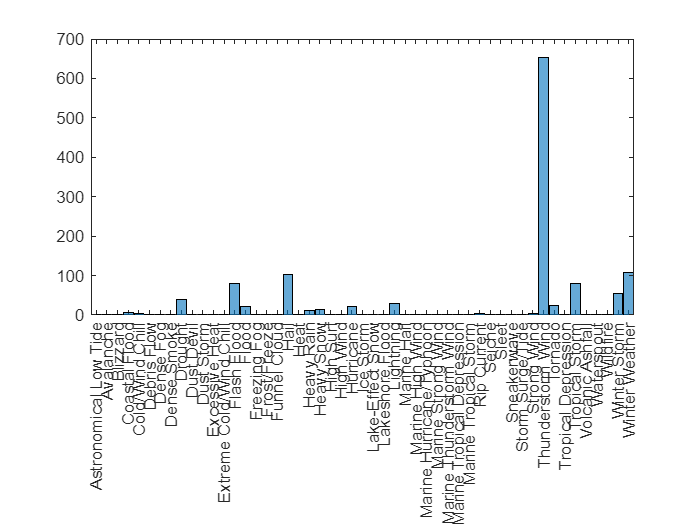

histogram(data_georgia.Event_Type)

data_cal = data(data.State == "CALIFORNIA",:)

data_cal = 1599×18 table
      State          Month        Event_Type       Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    __________    ____________    ___________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    _____________

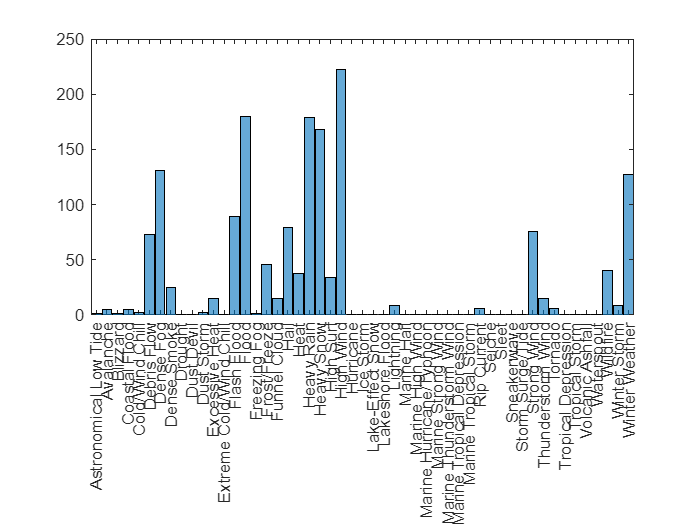

histogram(data_cal.Event_Type)

While in Georgia, most events were thunderstorms. However, in California, very few of such events. 

### Q6. Which states were affected by flood or flash flood?

data_flood= data(data.Event_Type == "Flash Flood" | data.Event_Type == "Flood",:) 

data_flood = 9073×18 table
        State            Month        Event_Type       Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    _____________    _____________    ___________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    ___

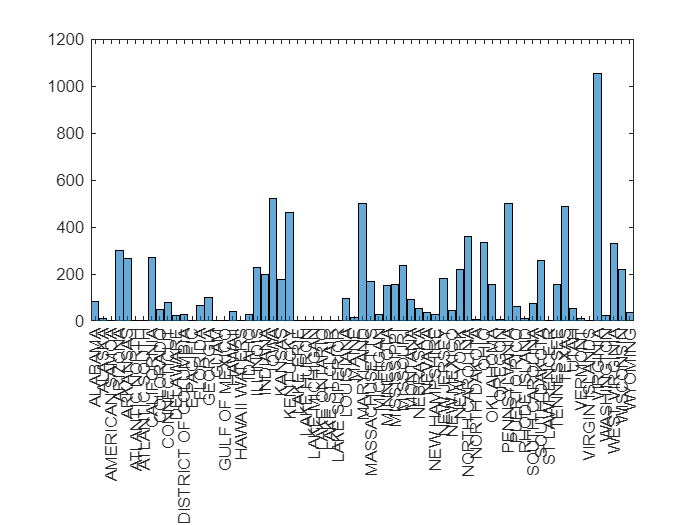

histogram(data_flood.State)

data_co_flood = data(data.Event_Type == "Coastal Flood",:)

data_co_flood = 320×18 table
       State         Month       Event_Type        Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ___________    _________    _____________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    _________

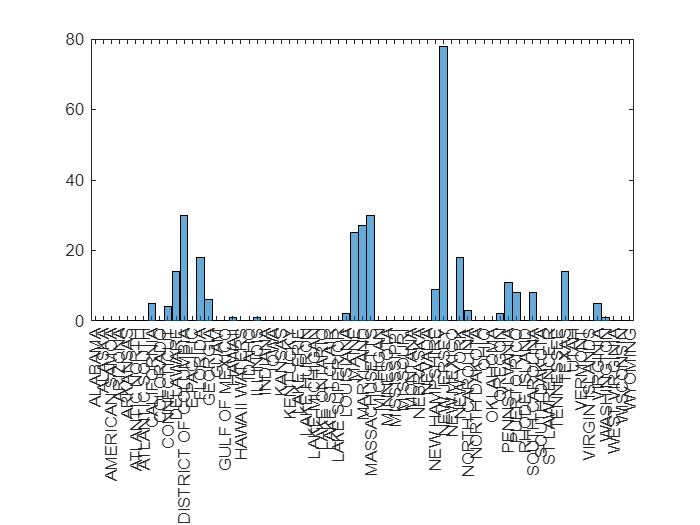

histogram(data_co_flood.State) 

So, coastal floods mostly affected New Jersey.

### Q7. Visualize locations of some events

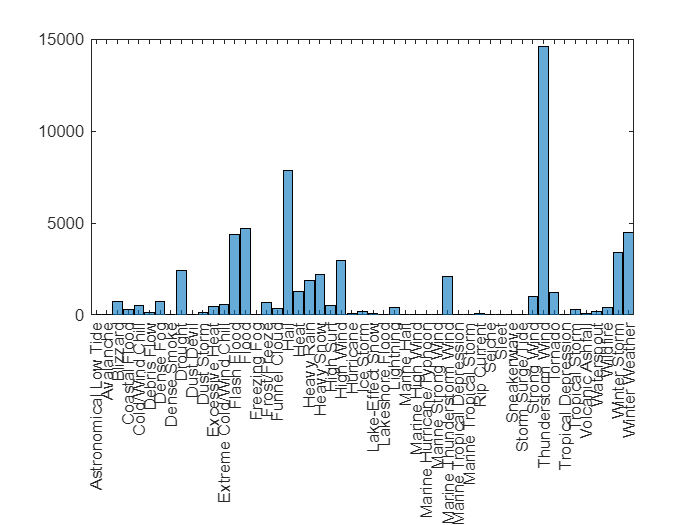

histogram(data.Event_Type)

data_ff = data(data.Event_Type =="Flash Flood",:)

data_ff = 4358×23 table
    EpisodeID      Event_ID           State           Year        Month          Event_Type         Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                     

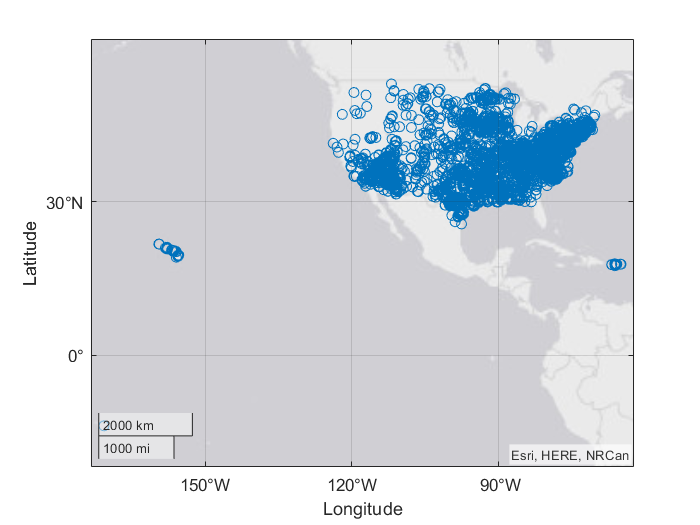

geoscatter(data_ff.Begin_Lat,data_ff.Begin_Lon)

### Q8. Which events caused highest deaths?

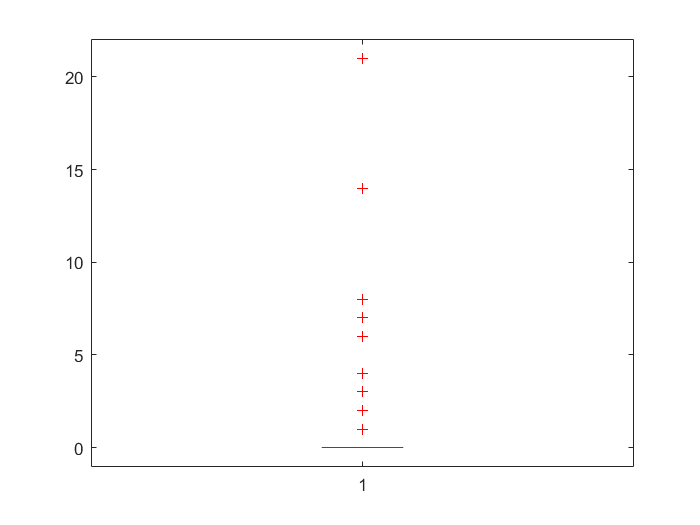

 boxplot(data.Deaths_Direct)

There are some particular cases where many deaths occurred.

death_dir = sortrows(data, "Deaths_Direct","descend")

death_dir = 61742×18 table
      State          Month           Event_Type         Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    __________    ____________    ________________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    _

As we can see, there is a debris flow in California in January 2018 that casued 21 deaths.

n.b. In January 2018, California experienced devastating **debris flows** (also referred to as **mudslides**) primarily in the coastal community of **Montecito** in Santa Barbara County. These debris flows were triggered by heavy rainfall falling on areas that had been recently burned by the **Thomas Fire**, one of the largest wildfires in California's history at the time.

The state of Nevada frequently suffered from Heat events, especially in the month of July, that caused several deaths.

data_heat= data(data.Event_Type == "Excessive Heat",:)

data_heat = 437×18 table
           State             Month        Event_Type        Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ____________________    ________    ______________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    

### Q9. Which events caused the highest damage to property?

sortrows(data, "Property_Cost","descend")

ans = 61742×18 table
     State         Month           Event_Type          Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ________    ____________    _________________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    _________

The data needs processing. We need to take care of the NaN values and combine all different costs.

data2= fillmissing(data.Property_Cost, "constant", 0)

data2 = 1.0e+10 *

         0
         0
    0.0000
    0.0000
         0
    0.0000
         0
         0
         0
         0


data.Property_Cost= data2

data = 61742×18 table
     State          Month           Event_Type          Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ________    _____________    _________________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    ______

sortrows(data, "Property_Cost","descend")

ans = 61742×18 table
        State             Month           Event_Type         Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ______________    _____________    ________________    ___________________    _________    ___________________    _______________    _________________    _____________    _______________    

Several events caused huge property damage. We want to group them together for more clear information.

gc= groupsummary(data, 'Event_Type', 'sum', 'Property_Cost')

gc = 51×3 table
          Event_Type           GroupCount    sum_Property_Cost
    _______________________    __________    _________________

    Astronomical Low Tide           33                   0    
    Avalanche                       16                   0    
    Blizzard                       748           3.527e+06    
    Coastal Flood                  320          1.4165e+07    
    Cold/Wind Chill                523                   0    
    Debris Flow                    136           4.765e+06    
    Dense Fog                      752             3.4e+05    
    Dense Smoke                     45                   0    
    Drought                       2410                   0    
    Dust Devil                       8            5.27e+05    
    Dust Storm                     113               9e+05    
    Excessive Heat                 437                   0    

sortrows(gc, "sum_Property_Cost","descend")

ans = 51×3 table
       Event_Type        GroupCount    sum_Property_Cost
    _________________    __________    _________________

    Wildfire                 416          1.8842e+10    
    Hurricane                 60          6.1347e+09    
    Storm Surge/Tide          26          1.0502e+09    
    Hail                    7861          7.2278e+08    
    Tornado                 1248          6.7025e+08    
    Flash Flood             4358          5.5975e+08    
    Flood                   4715          5.2815e+08    
    Tropical Storm           317          3.1055e+08    
    Thunderstorm Wind      14585          1.3926e+08    
    Winter Storm            3375          6.8832e+07    
    High Wind               2944          5.3457e+07    
    Lakeshore Flood           10           2.595e+07    
    Lightning                393          1.6062e+07    
    Coastal Flood        

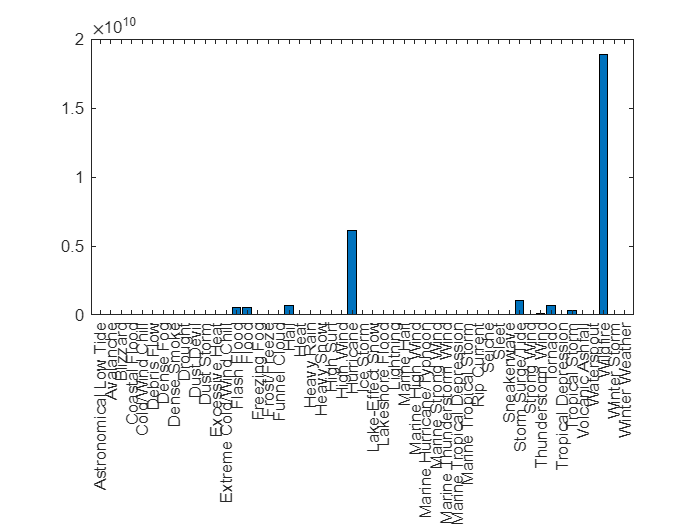

bar(gc.Event_Type,gc.sum_Property_Cost,'DisplayName','gc.sum_Property_Cost')

As we can see, most property damage was caused by Wildfire. 2nd most is from Hurricane.

### Q10. Event visualization in Georgia

data_georgia = data(data.State == "GEORGIA",:)

data_georgia = 1257×23 table
    EpisodeID      Event_ID        State       Year       Month          Event_Type         Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                  Episode_Narrative                                                                                                    

data_georgia= sortrows(data_georgia,"Event_Type","ascend")

data_georgia = 1257×23 table
    EpisodeID      Event_ID        State       Year       Month            Event_Type           Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                    

data_georgia.Month = string(data_georgia.Month);
data_georgia.Month = categorical(data_georgia.Month);

data_georgia_jan= data_georgia(data_georgia.Month == 'January',:)

data_georgia_jan = 189×23 table
    EpisodeID      Event_ID        State       Year     Month         Event_Type           Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                      

data_georgia_july= data_georgia(data_georgia.Month == 'July',:)

data_georgia_july = 201×23 table
    EpisodeID      Event_ID        State       Year    Month      Event_Type         Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                           